# Homework 04 - System Performance

Please add your name, section, and semester information to the fields below

StudentName = "Edward Ramirez"; % First Last
Section = "A09"; % ex. A01
Semester = "Spring 2025"; % ex. Spring 2025

## Background

In this block you will investigate a part which is experiencing resonance due to a periodic force. You will determine whether adding a lumped-mass extension can reduce the magnitude of its excitation below a client's specification. The client has provided samples to test this proposed solution, under the assumption that the part can be theoretically modeled as a rectangular cantilever beam (Figure 1). Part of your task is to determine the adequacy of this model by comparing the measured response to the designed response, which should both be the same if the model is accurate.

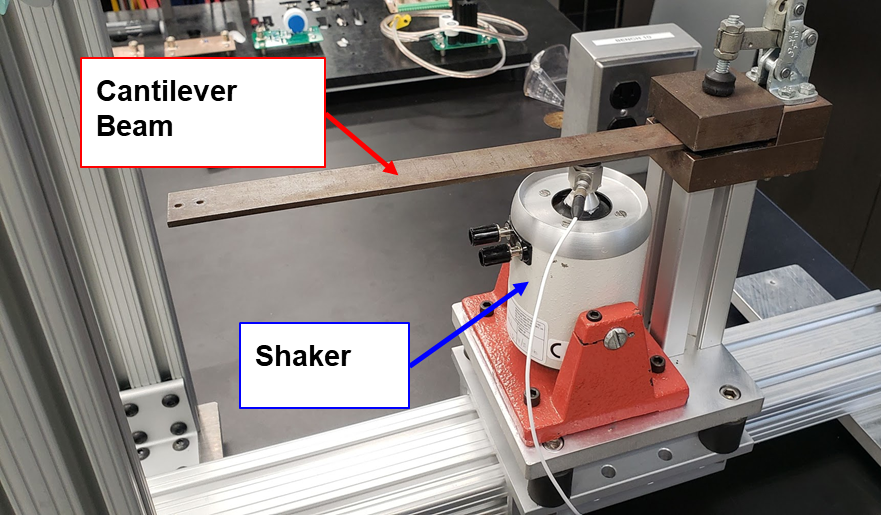

*Figure 1: Wing sample modeled as a cantilever beam.*

You will be testing the model due to several inputs to determine the system response for forced vibration across a range of possible operating frequencies. You will model the relationship between the input force and output displacement response. Figure 2 shows the test setup which consists of a shaker applying a harmonic force to the part, which will be measured using a piezoelectric force transducer. The output response will be measured using a laser doppler vibrometer (LDV). The ELVIS III board will be used to both command the shaker and to record the input force and output response of the beam.  

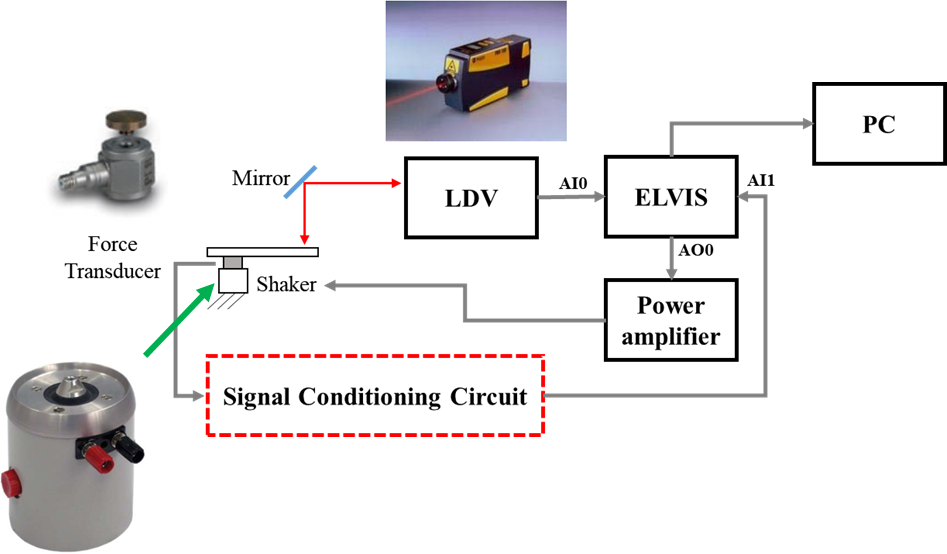

*Figure 2: Schematic of test setup for measuring the free and forced response of the beam.*

## Data

A sample dataset, *Homework_4_Data.mat*, that you will use in this homework analysis can be found in the assignment on Canvas.

load( 'Homework_4_Data.mat' );

## Theoretical Natural Frequency

Under the assumption that the part is a rectangular cantilever beam that is free to vibrate, the theoretical first natural frequency of the beam can be calculated in terms of the length, $L$, width, $b$, thickness, $h$, density, $\rho$, and Young’s Modulus, $E$, in Hertz using the lumped mass approximation (Figure 3). Using this approximation, the natural frequency of the beam, $f_n$, can be calculated as:


$$f_n =\frac{h}{2\pi L^2 }\sqrt{\frac{E}{\rho }}$$


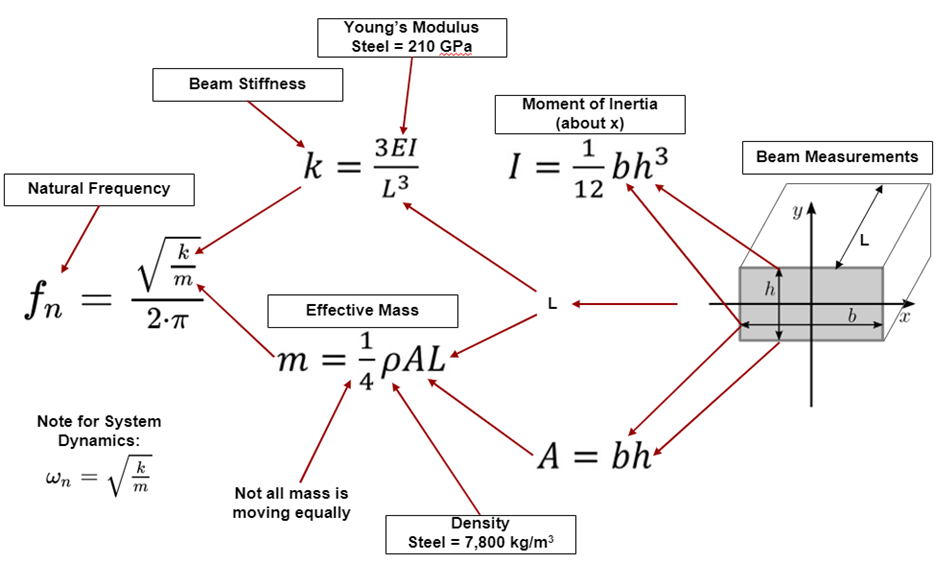

*Figure 3: Lumped mass approximation of natural frequency for a rectangular cross-section cantilever beam.*

For this homework and during the lab block, you can assume the following material properties of the beam.

% Material Properties of the Test Beam
E_GPa = 210; % GPa, Young's Modulus of steel
rho_kg_m3 = 7800; % kg/m^3, density of steel

During the lab block, you will measure the beam using calipers or a ruler. For this homework you can use the following beam dimensions and resolution of the digital calipers in your calculations.

% Dimensional Measurements and Properties of the Test Beam
L_mm = 228; % mm, length of beam
b_mm = 25.4; % mm, width of beam
h_mm = 3.15; % mm, thickness of beam
r_mm = 0.01; % mm, resolution of the digital calipers

### Expected Value

#### Problem 1

What is the theoretical natural frequency of the cantilever beam, $f_{n,\textrm{theory}}$, using the lumped mass approximation in **Hertz**? (*Hint: It should be between 45 and 55 Hz.*)

% Calculate Ix (MoI about x-axis)
Ix = (1./12).*(b_mm).*(h_mm.^3); % (1/12)(bh^3) [mm]
% Calculate m (effective mass)
csArea_m2 = (b_mm.*1e-3).*(h_mm.*1e-3); % [m2] 
effectiveMass = (1./4).*(rho_kg_m3).*(csArea_m2).*(L_mm.*1e-3); % [kg]
% Calculate k (beam stiffness)
beamStiffness = (3.*E_GPa.*Ix)./(L_mm.^3); % [kN/mm]
% Calculate fN (theoretical natural frequency)
f_n_theory_kHz = (sqrt(beamStiffness./effectiveMass))./(2.*pi); % [kHz]
% Convert fN to Hz
f_n_theory_Hz = f_n_theory_kHz .* 1e3; % [Hz]

fprintf( 'f_n_theory = %.3g Hz\n', f_n_theory_Hz ); % Print answer

f_n_theory = 50 Hz


### Uncertainty

When reporting calculated values from analytical models from measurements, in addition to the expected value, you want account for the uncertainty of the measurements (i.e. $f_n =X\pm Y\;\textrm{Hz}$). For this analysis, assume the uncertainty of the material properties are negligible as compared to the uncertainty due to the beam measurements.

#### Problem 2

What is the uncertainty of the natural frequency **(in Hertz) **due to the uncertainty of the length measurement, $u_{f_n ,L}$, to a 95.4% level of certainty? *(Hint: The uncertainty should be less than ±0.01 Hz.)*

% digitalUncertainty = K*(p/sqrt(3))
K = 2; % 95.4% level of certainty (K = 2)
caliperPrecision = r_mm./2; % mm
caliperUncertainty = K.*(caliperPrecision./sqrt(3)); % mm
% convert caliper uncertainty to freq. uncertainty
u_f_n_L_Hz = 0;
fprintf( 'u_f_n_L = %.4f Hz\n', u_f_n_L_Hz ); % Print answer

u_f_n_L = 0.0058 Hz


#### Problem 3

What is the uncertainty of the natural frequency **(in Hertz) **due to the uncertainty of the width measurement, $u_{f_n ,b}$, to a 95.4% level of certainty? *(Hint: The uncertainty should be less than ±0.01 Hz.)*


fprintf( 'u_f_n_b = %.3g Hz\n', u_f_n_b_Hz ); % Print answer

u_f_n_b = 0 Hz


#### Problem 4

What is the uncertainty of the natural frequency **(in Hertz) **due to the uncertainty of the thickness measurement, $u_{f_n ,h}$, to a 95.4% level of certainty? *(Hint: The uncertainty should be less than ±1.0 Hz.)*

fprintf( 'u_f_n_h = %.3g Hz\n', u_f_n_h_Hz ); % Print answer

u_f_n_h = 0.00408 Hz


#### Problem 5

What is the **total uncertainty** of the natural frequency **(in Hertz) **due to the beam measurement, $u_{f_n }$, to a 95.4% level of certainty? *(Hint: The uncertainty should be less than ±1.0 Hz.)*

fprintf( 'u_f_n = %.3g Hz\n', u_f_n_Hz ); % Print answer

u_f_n = 3.11e-05 Hz


## Free Response

When designing an experimentation plan, you want to make sure you collect data near the important points of interest for your system. For this block you will be selecting discrete frequencies to test the beam using harmonic forcing. You will want to ensure you collect data at the natural frequency of the beam. However, you will not initially know natural frequency for the actual physical system. This can be determined experimentally by analyzing the free response of the system to an initial displacement. As sample set of free response LVD data is in *Homework_4_Data.mat*.

% LDV free response data
t_free_s; % s, time vector
V_free_V; % V, LDV voltage

#### Problem 6

Using the LDV time, $t_{\textrm{free}}$, and voltage, $V_{\textrm{free}}$, data, what is the natural frequency of the beam, $f_{n,\textrm{free}}$, in **Hertz**? *(Hint: It should be between 45 & 55 Hz. It may be helpful to plot the data to select appropriate datapoints to calculate the frequency.) *

fprintf( 'f_n_free = %.3g Hz\n', f_n_free_Hz ); % Print answer

f_n_free = 46.5 Hz


## Forced Response

To determine the response of the system at frequencies other than the natural frequency, the sample will be excited with two forms of forcing inputs: sinusoidal and white noise. You will calculate the transfer function,$\textrm{TF}\left(f\right)$, between the amplitude of the forcing,$F$, and the displacement response of the system,$X$, at different frequencies:


$$\textrm{TF}\left(f\right)=\frac{\left|X\left(f\right)\right|}{\left|F\left(f\right)\right|}$$


### Laser Doppler Vibrometer

During the lab you will be measuring the response of the beam using a laser doppler vibrometer (LDV) due several different inputs. The LDV will be positioned so that it is focused on the free end of the cantilever beam, as shown in Figure 4. While the NI ELVIS III board is capable of reading both positive and negative voltages (+/- 10V), the LDV is limited to outputting +/- 4V. If the responsible of the beam is too large, the LDV will be overdriven, and the data collected will not be accurate.

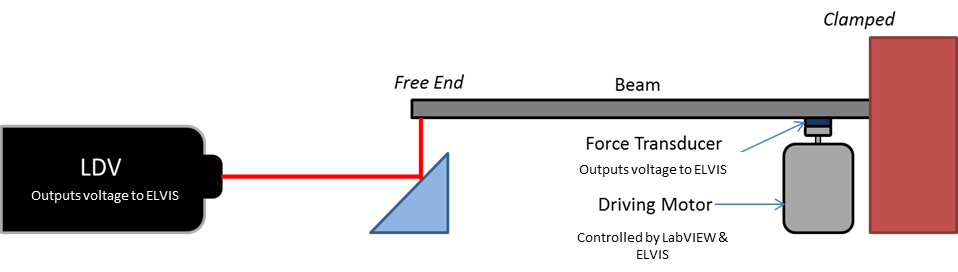

Figure 4: Schematic of LDV, beam, and shaker setup.

% LDV specifications
S_LDV_V_m_s = 40; % V/(m/s), LDV sensitivity

#### Problem 7

When you measure a vibrating beam with a LDV, it returns a voltage. What quantity is this voltage **linearly **related to?

Problem_7_answer = "Displacement"

Problem_7_answer = "Displacement"

### Force Transducer

The LabVIEW VI used to control the testing allows for varying input voltage and frequency into the shaker that will excite the part. The resulting force that is applied to the beam will be measured by a piezoelectric force transducer between the shaker and the beam. Due to the low voltage and current of the output of the transducer, the signal will be conditioned before acquisition by the ELVIS III board. The signal conditioning circuit (Figure 5) consists of a charge amplifier which provides power the transducer, an AC coupling circuit which will remove any offset voltage from the signal at zero voltage, a 200x operational amplifier to boost the voltage, and a 2000 Hz low pass filter to remove noise before acquisition.

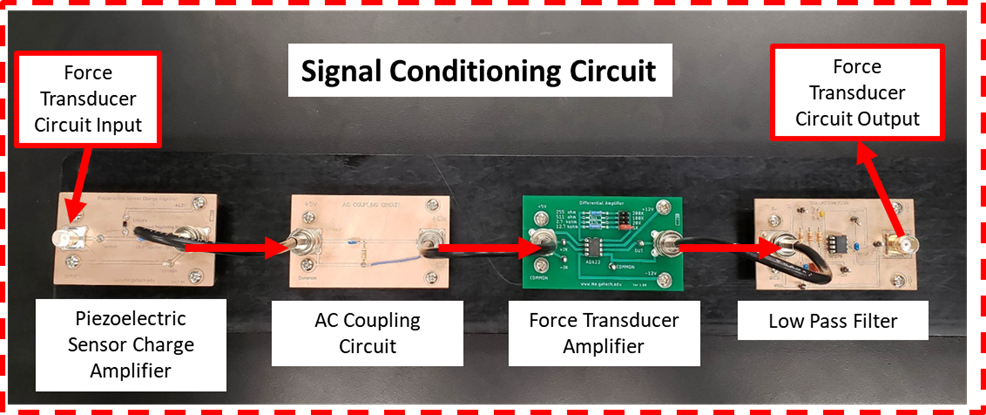

*Figure 5: Piezoelectric force transducer signal conditioning circuit*

The piezoelectric force transducer and the signal conditioning circuit has the following specifications:

% Piezoelectric force transducer and the signal conditioning circuit specifications
S_FT_V_N = 0.011241; % V/N, force transducer sensitivity
G_FT_amp = 200; % V/V, force transducer signal conditioning amplifier gain

### Sinusoidal Forcing

Exciting the beam with sinusoidal forcing allows for characterizing the beam response at specific frequencies. Because the input will consist of a single frequency, it will typically be more accurate than white noise force (assuming you are within the operating ranges of the shaker, force transducer, and LDV). The tradeoff is it is more tedious and time consuming to determine the transfer function across a large range of frequencies. You will conduct sinusoidal forcing analysis for the beam with and without the damper.

As sample set of sinusoidal response data for the beam as recorded by the ELVIS board and processed by the VI is in *Homework_4_Data.mat: the *input frequency into the shaker, $f_{\sin }$, the shaker input voltage amplitude, $V_{\textrm{shaker},\sin }$, the LDV peak-to-peak voltage amplitude,$V_{\textrm{LDV},\sin }$, and the force transducer peak-to-peak voltage amplitude,$V_{\textrm{FT},\sin }$, 

% Sinusoidal forcing inputs and outputs
f_sin_Hz; % Hz, input frequency to shaker
V_shaker_sin_V; % V, shaker input voltage amplitude
V_LDV_sin_Vpp; % V, LDV output peak-to-peak voltage amplitude from ELVIS
V_FT_sin_Vpp; % V, Force transducer peak-to-peak voltage amplitude from ELVIS

#### Problem 8

For the LDV data, calculate the peak-to-peak velocity amplitude, ${\mathrm{V}}_{\sin ,\textrm{pp}}$, in **meters per second. ***(Hint: For 29 Hz, it should be between 0.05 & 0.07 m/s.) *

fprintf( 'f_sin = %.3g Hz, V_sin = %.3g m/s\n', f_sin_Hz(1), V_sin_m_s(1) ); % Print answer

f_sin = 29 Hz, V_sin = 0.00255 m/s


#### Problem 9

Calculate the displacement peak-to-peak amplitude, $X_{\sin ,\textrm{pp}}$, in **meters. ***(Hint: For 29 Hz, it should be between 3E-4 & 4E-4 m.) *

fprintf( 'f_sin = %.3g Hz, X_sin = %.3g m\n', f_sin_Hz(1), X_sin_m_pp(1) ); % Print answer

f_sin = 29 Hz, X_sin = -1.4e-05 m


#### Problem 10

Calculate the force peak-to-peak amplitude, $F_{\sin ,\textrm{pp}}$, in **Newtons. ***(Hint: For 29 Hz, it should be between 1.1 & 1.3 N.) *

fprintf( 'f_sin = %.3g Hz, F_sin = %.3g N\n', f_sin_Hz(1), F_sin_N_pp(1) ); % Print answer

f_sin = 29 Hz, F_sin = 6.12 N


#### Problem 11

Calculate the transfer function, $TF_{\sin }$, in **meters per** **Newtons. ***(Hint: For 29 Hz, it should be between 2E-4 & 4E-4 m/N.)  *

fprintf( 'f_sin = %.3g Hz, TF_sin = %.3e m/N\n', f_sin_Hz(1), TF_sin_m_N(1) ); % Print answer

f_sin = 29 Hz, TF_sin = -2.287e-06 m/N


#### Problem 12

Calculate the transfer function, $TF_{\textrm{dB},\sin }$, in **decibels** with a 1 m/N reference value**. ***(Hint: For 29 Hz, it should be between -80 & -60 dB re 1 m/N. Base-10 logarithm in log10() in MATLAB.) *

fprintf( 'f_sin = %.3g Hz, TF_dB_sin = %.3g dB re 1 m/N\n', f_sin_Hz(1), TF_dB_sin(1) ); % Print answer

f_sin = 29 Hz, TF_dB_sin = -113 dB re 1 m/N


### White Noise Forcing

White noise is a random signal where the intensity is equal across all frequencies. By examining the beam’s response in the frequency domain, the transfer function of the beam can be calculated across multiple frequencies quickly. However, since the signal is random, the calculation is not as accurate as using sinusoidal forcing. During lab you will average multiple tests of white noise to improve the accuracy, but we always want to double-check white noise data by performing sinusoidal forcing tests at specific frequencies of interest.

As sample set of white noise response data for the beam with and without the damper as recorded by the ELVIS board and processed by the VI is in *Homework_4_Data.mat: *the frequency range, $f_{\textrm{white}}$, the transfer function for the beam, ${\textrm{TF}}_{\textrm{white},1\;\textrm{DoF}}$, and the transfer function for the beam with the damper, ${\textrm{TF}}_{\textrm{white},2\;\textrm{DoF}}$.

% White noise forcing outputs
f_white_Hz; % Hz, frequency range
TF_white_1_DoF_dB; % dB re 1 m/N, white noise transfer function for the original beam
TF_white_2_DoF_dB; % dB re 1 m/N, white noise transfer function for the beam with the damper

#### Problem 13

Create a well-formatted figure showing the white noise forcing transfer functions for the beam with, ${\textrm{TF}}_{\textrm{white},1\;\textrm{DoF}}$, and without the damper, ${\textrm{TF}}_{\textrm{white},2\;\textrm{DoF}}$, versus the frequency for the white noise data, $f_{\textrm{white}}$, corresponding to a 0 to 100 Hz range. *(Note: In report you will want to add additional data and annotations.) *

#### Problem 14

Based upon the white noise data, what is the effectiveness of the damper at the natural frequency of the beam without the damper, ${\bigtriangleup \textrm{TF}}_{n,\textrm{white}}$, in **decibels** with a 1 m/N reference value? *(Hint: It should be between -60 and -50 dB re 1 m/N.) *

fprintf( '∆TF_n_white = %.3g dB re 1 m/N\n', delta_TF_n_white_dB ); % Print answer

∆TF_n_white = 0 dB re 1 m/N


#### **Problem 15**

Based upon the white noise data, what is the effectiveness of the damper at the cruise speed of 2400 rpm, ${\bigtriangleup \textrm{TF}}_{\textrm{cruise},\textrm{white}}$,  in **decibels** with a 1 m/N reference value? *(Hint: It should be between -10 and -20 dB re 1 m/N.)*

fprintf( '∆TF_cruise_white = %.3g dB re 1 m/N\n', delta_TF_cruise_white_dB ); % Print answer

∆TF_cruise_white = 14.7 dB re 1 m/N
